clearvars; clc;

# Esercitazione 4

#### Definitions

A=[0 1;0 -1];
B=[0 1]';
C=[1 0];
D=0;

sys=ss(A,B,C,D);

Ts=0.05;

x0=[0.8 0]';

n=2;

#### Discretize

sys_dt=c2d(sys,Ts,'zoh');

Ad=sys_dt.A;
Bd=sys_dt.B;
Cd=sys_dt.C;
Dd=sys_dt.D;

#### Checking reachability

Mr=ctrb(Ad,Bd);
rho_Mr=rank(Mr);
if rho_Mr==n
    disp('System is reachable');
else
    disp('System is not reachable');
end

System is reachable


#### Zero regulation

q11=100;
q22=1;
r=0.1;

Q=diag([q11 q22]);
R=r;
Cq=chol(Q);
Mo=obsv(Ad,Cq);
rho_Mo=rank(Mo);
K=dlqr(Ad,Bd,Q,R);

#### Simulation

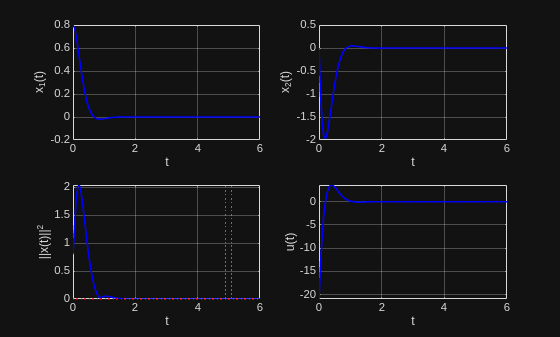

sys_x=ss(A,B,eye(n),0);

t_sim=6;
out=sim('sim_esercitazione_4');
figure(1);

subplot(221), 
plot(out.x.time,out.x.data(:,1),'b','linew',1.2),
grid on, zoom on, xlim([0 6]);
xlabel('t'), ylabel('x_1(t)');

subplot(222), 
plot(out.x.time,out.x.data(:,2),'b','linew',1.2), grid on,
zoom on,xlabel('t'), ylabel('x_2(t)'), xlim([0 6]);

subplot(223), 
plot(out.x.time,sqrt(out.x.data(:,1) .^2+out.x.data(:,2) .^2),'b','linew',1.2),
zoom on, grid on
yline(1e-5,':r','linew',1.2)
yline(-1e-5,':r','linew',1.2)
xline(5-2/100*5,':g');
xline(5+2/100*5,':g');
xlabel('t'), ylabel('||x(t)||^2'), xlim([0 6]);

subplot(224), plot(out.u.time,out.u.data,'b','linew',1.2),
grid on, zoom on,
xlabel('t'), ylabel('u(t)'), xlim([0 6]);